# Class 2

cashflow1=[-2000,1200,1500];
npv1=pvvar(cashflow1,0.1)%present value variable

npv1 =         330.58


fpv1=fvvar(cashflow1,0.1)

fpv1 =         400.00


irr1=irr(cashflow1)

irr1 =           0.22


cashflow2=[-2000,700,3500];
npv2=pvvar(cashflow2,0.1)

npv2 =        1528.93


irr2=irr(cashflow2)

irr2 =           0.51


pvs=[npv1,npv2;irr1,irr2]

pvs =         330.58       1528.93
          0.22          0.51


help amortize

 amortize Amortization.
    amortize returns the principal and interest portions of a loan paid by a
    periodic payment and computes the remaining balance of the original loan
    amount and the periodic payment.
 
    [PRINP, INTP, BAL, P] = amortize(RATE, NPER, PV)
    [PRINP, INTP, BAL, P] = amortize(RATE, NPER, PV, FV, DUE)
 
    Optional Inputs: FV, DUE
 
    Inputs:
     RATE - Scalar value for the periodic interest rate charged.
 
     NPER - Scalar value for the number of payment periods.
 
       PV - Scalar value for the present value of the loan.
 
    Optional Inputs:
       FV - Scalar value for the future value of the loan. Default FV = 0.
 
      DUE - Scalar value that specifies whether the payments are made at the
            beginning (due = 1) or end (Default: due = 0) of the period.
 
    prinp is a vector of the principal paid in each period, intp is a vector
    of the interest paid in each period, bal is the remaining balance o

annual_rate=0.05;
monthly_rate=(1+annual_rate)^(1/12)-1;
NumPeriods=5*12;
Loan=250000;
[Principlal,Interest,Balance,Payment]=amortize(monthly_rate,NumPeriods,Loan)

Principlal =        3686.57       3701.59       3716.67       3731.81       3747.01       3762.28       3777.61       3793.00       3808.45       3823.97       3839.55       3855.19       3870.90       3886.67       3902.50       3918.40       3934.37       3950.39       3966.49       3982.65       3998.87       4015.17       4031.53       4047.95       4064.44       4081.00       4097.63       4114.32       4131.08       4147.91       4164.81       4181.78       4198.82       4215.93       4233.10       4250.35       4267.66       4285.05       4302.51       4320.04       4337.64       4355.31       4373.05       4390.87       4408.76       4426.72       4444.76       4462.86       4481.05       4499.30


Interest =        1018.53       1003.51        988.43        973.29        958.08        942.82        927.49        912.10        896.65        881.13        865.55        849.91        834.20        818.43        802.60        786.70        770.73        754.70        738.61        722.45        706.22        689.93        673.57        657.15        640.66        624.10        607.47        590.78        574.02        557.19        540.29        523.32        506.28        489.17        472.00        454.75        437.44        420.05        402.59        385.06        367.46        349.79        332.05        314.23        296.34        278.38        260.34        242.23        224.05        205.80


Balance =      246313.43     242611.84     238895.17     235163.36     231416.35     227654.07     223876.46     220083.46     216275.01     212451.04     208611.49     204756.30     200885.40     196998.74     193096.23     189177.83     185243.47     181293.07     177326.58     173343.93     169345.06     165329.89     161298.37     157250.42     153185.97     149104.97     145007.35     140893.02     136761.94     132614.03     128449.21     124267.43     120068.61     115852.69     111619.58     107369.24     103101.57      98816.52      94514.01      90193.98      85856.34      81501.03      77127.97      72737.10      68328.34      63901.62      59456.86      54994.00      50512.95      46013.65


Payment =        4705.10


%transpose 
payment_vector=repmat(Payment,60,1)

payment_vector =        4705.10
       4705.10
       4705.10
       4705.10
       4705.10
       4705.10
       4705.10
       4705.10
       4705.10
       4705.10


amor_table=[Balance',Interest',Principlal',payment_vector]

amor_table =      246313.43       1018.53       3686.57       4705.10
     242611.84       1003.51       3701.59       4705.10
     238895.17        988.43       3716.67       4705.10
     235163.36        973.29       3731.81       4705.10
     231416.35        958.08       3747.01       4705.10
     227654.07        942.82       3762.28       4705.10
     223876.46        927.49       3777.61       4705.10
     220083.46        912.10       3793.00       4705.10
     216275.01        896.65       3808.45       4705.10
     212451.04        881.13       3823.97       4705.10


Principal=500000

n=360months;

annual int rate=6%;

- Amontize: Month, Balance, Capital, Interest, Payment

- $\Delta$T 120 month what is the amount i owe to the banck; How much i have paid in interest (Up to monthe 120 included)

annual_rate1=0.06;
month_rate=(1+annual_rate1)^(1/12)-1;
NumPeriods1=360;
Principal=500000;
[Principal,Interest,Balance,Payment]=amortize(month_rate,NumPeriods1,Principal)

Principal =         513.08        515.57        518.08        520.61        523.14        525.69        528.24        530.82        533.40        536.00        538.61        541.23        543.86        546.51        549.17        551.84        554.53        557.23        559.94        562.67        565.40        568.16        570.92        573.70        576.49        579.30        582.12        584.95        587.80        590.66        593.54        596.43        599.33        602.25        605.18        608.12        611.08        614.06        617.05        620.05        623.07        626.10        629.15        632.21        635.29        638.38        641.49        644.61        647.75        650.90


Interest =        2433.78       2431.28       2428.77       2426.25       2423.71       2421.17       2418.61       2416.04       2413.45       2410.86       2408.25       2405.63       2402.99       2400.34       2397.68       2395.01       2392.32       2389.62       2386.91       2384.19       2381.45       2378.70       2375.93       2373.15       2370.36       2367.55       2364.73       2361.90       2359.05       2356.19       2353.32       2350.43       2347.52       2344.61       2341.68       2338.73       2335.77       2332.79       2329.81       2326.80       2323.78       2320.75       2317.70       2314.64       2311.56       2308.47       2305.36       2302.24       2299.10       2295.95


Balance =      499486.92     498971.35     498453.27     497932.66     497409.52     496883.83     496355.59     495824.77     495291.37     494755.38     494216.77     493675.54     493131.68     492585.17     492036.01     491484.16     490929.64     490372.41     489812.47     489249.80     488684.40     488116.24     487545.32     486971.62     486395.13     485815.83     485233.71     484648.76     484060.96     483470.30     482876.76     482280.34     481681.01     481078.76     480473.59     479865.46     479254.38     478640.32     478023.28     477403.23     476780.16     476154.06     475524.91     474892.70     474257.41     473619.03     472977.54     472332.93     471685.19     471034.29


Payment =        2946.85


new_pay_array=[Principal',Interest',Balance']

new_pay_array =         513.08       2433.78     499486.92
        515.57       2431.28     498971.35
        518.08       2428.77     498453.27
        520.61       2426.25     497932.66
        523.14       2423.71     497409.52
        525.69       2421.17     496883.83
        528.24       2418.61     496355.59
        530.82       2416.04     495824.77
        533.40       2413.45     495291.37
        536.00       2410.86     494755.38


payment_vector=repmat(Payment,NumPeriods1,1);
new_pay_array(120,:);
sum(new_pay_array(1:120,2))

ans =      270260.90


amor_table=[[1:NumPeriods1]',Principal',Interest',Balance',payment_vector];
amor_table(1:10,1)

ans =           1.00
          2.00
          3.00
          4.00
          5.00
          6.00
          7.00
          8.00
          9.00
         10.00


help format

 format Set output format.
    format with no inputs sets the output format to the default appropriate
    for the class of the variable. For float variables, the default is
    format SHORT.
 
    format does not affect how MATLAB computations are done. Computations
    on float variables, namely single or double, are done in appropriate
    floating point precision, no matter how those variables are displayed. 
    Computations on integer variables are done natively in integer. Integer
    variables are always displayed to the appropriate number of digits for
    the class, for example, 3 digits to display the INT8 range -128:127.
    format SHORT and LONG do not affect the display of integer variables.
 
    format may be used to switch between different output display formats
    of all float variables as follows:
      format SHORT     Short fixed point format wit

x=linspace(0,1*pi,11)

x =              0          0.31          0.63          0.94          1.26          1.57          1.88          2.20          2.51          2.83          3.14


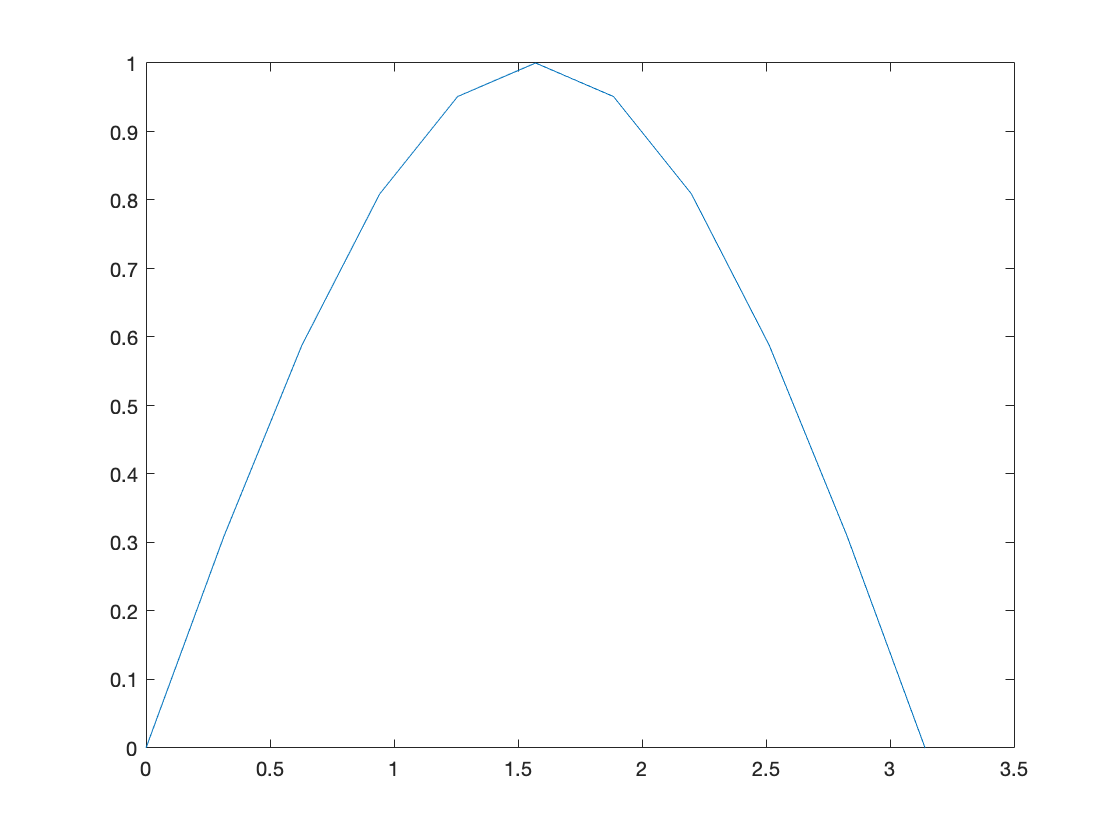

y=sin(x);
z=cos(x);
plot(x,y)

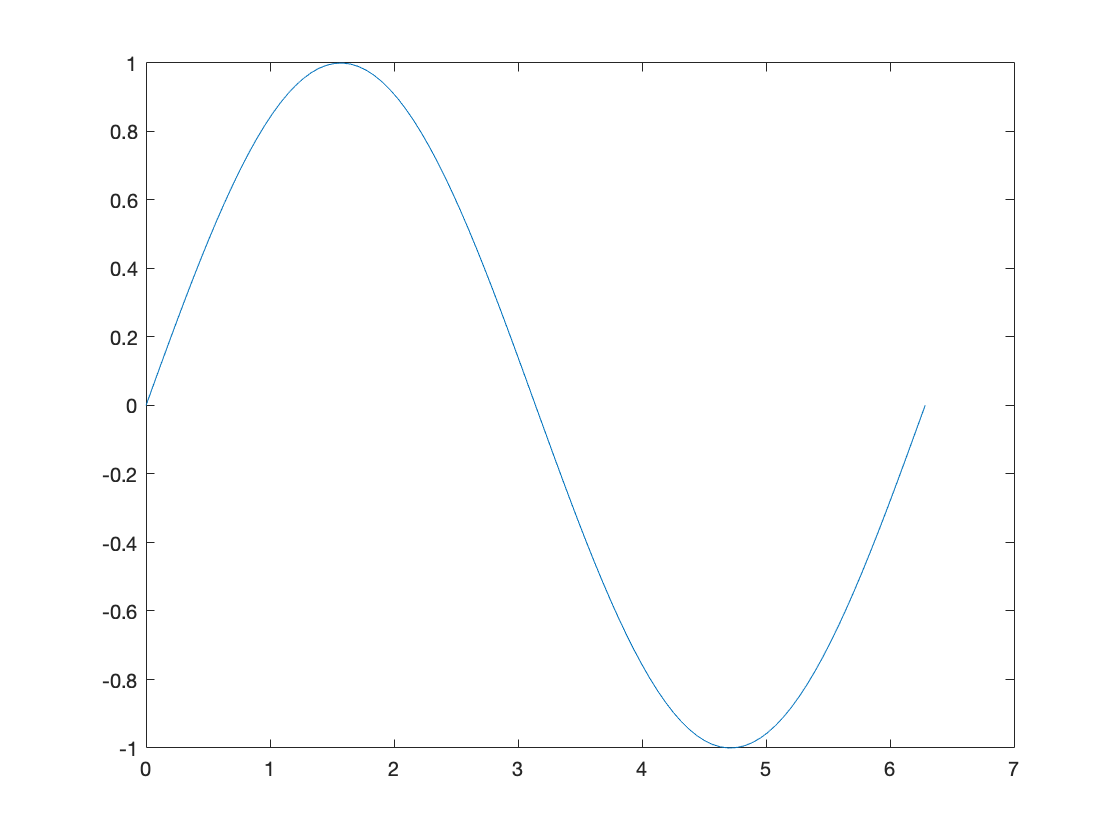

x=linspace(0,2*pi,100);
y=sin(x);
z=cos(x);
plot(x,y)

figure
plot(x,y)
y1=sin(x);
hold on %add more on the same figure 
plot(x,y1,"r")  
hold on 
plot(x,z,"b")
xlabel("x")
ylabel("sin(x) and cos(x)")
title("sin and cos functions")
text(2.5,0.7,"sin(x)")
legend('cos(x)','sin(x)')

new one

plot(Balance,'b');hold on
plot(cumsum(Principal),'--k')
plot(cumsum(Interest),':r')
load disney.mat
whos

  Name                  Size             Bytes  Class     Attributes

  Balance               1x360             2880  double              
  Interest              1x360             2880  double              
  Loan                  1x1                  8  double              
  NumPeriods            1x1                  8  double              
  NumPeriods1           1x1                  8  double              
  Payment               1x1                  8  double              
  Principal             1x360             2880  double              
  Principlal            1x60               480  double              
  a                     1x30               240  double              
  amor_table          360x5              14400  double              
  annual_rate           1x1                  8  double              
  annual_rate1          1x1                  8  double              
  ans                  10x1                 80  double              
  b                     1x30     

[i,j]=size(dis_LOW)

i =         782.00


j =           1.00


highlow(dis_OPEN(i-50:i),dis_HIGH(i-50:i),dis_LOW(i-50:i),dis_CLOSE(i-50:i))

load ibm.dat
whos

  Name                  Size             Bytes  Class     Attributes

  Balance               1x360             2880  double              
  Interest              1x360             2880  double              
  Loan                  1x1                  8  double              
  NumPeriods            1x1                  8  double              
  NumPeriods1           1x1                  8  double              
  Payment               1x1                  8  double              
  Principal             1x360             2880  double              
  Principlal            1x60               480  double              
  a                     1x30               240  double              
  amor_table          360x5              14400  double              
  annual_rate           1x1                  8  double              
  annual_rate1          1x1                  8  double              
  ans                  10x1                 80  double              
  b                     1x30     

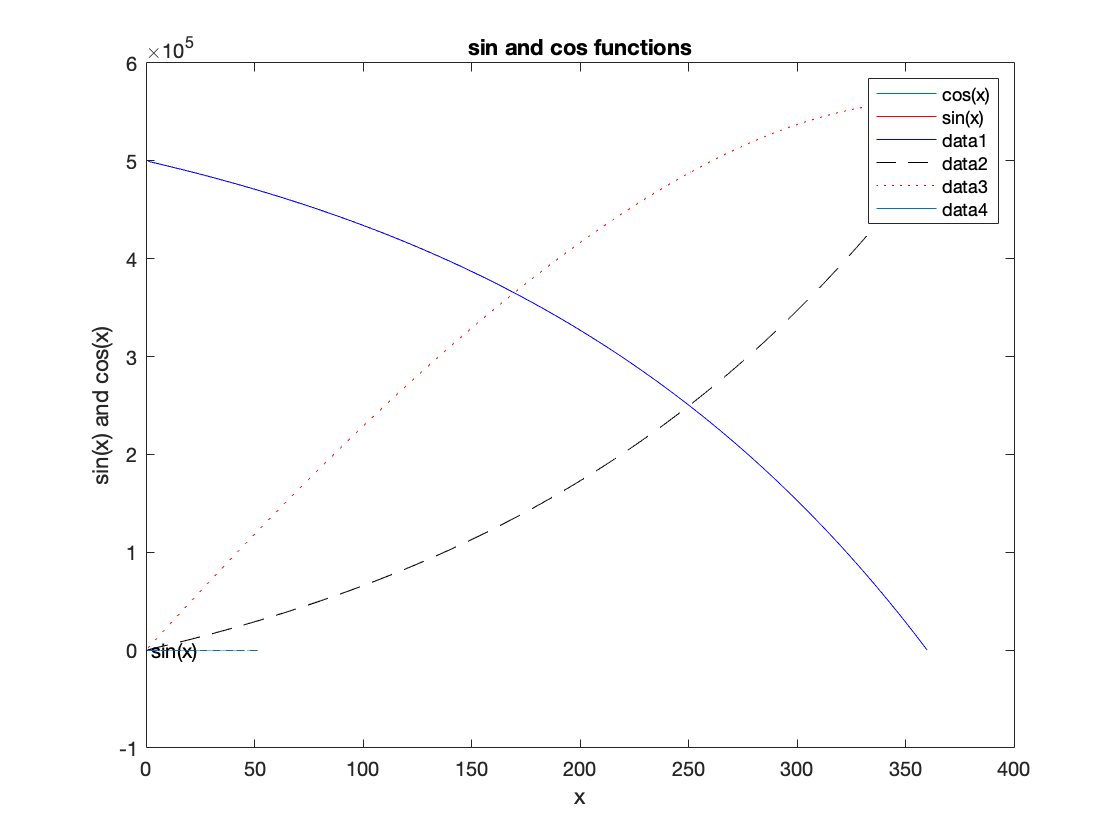

hold off

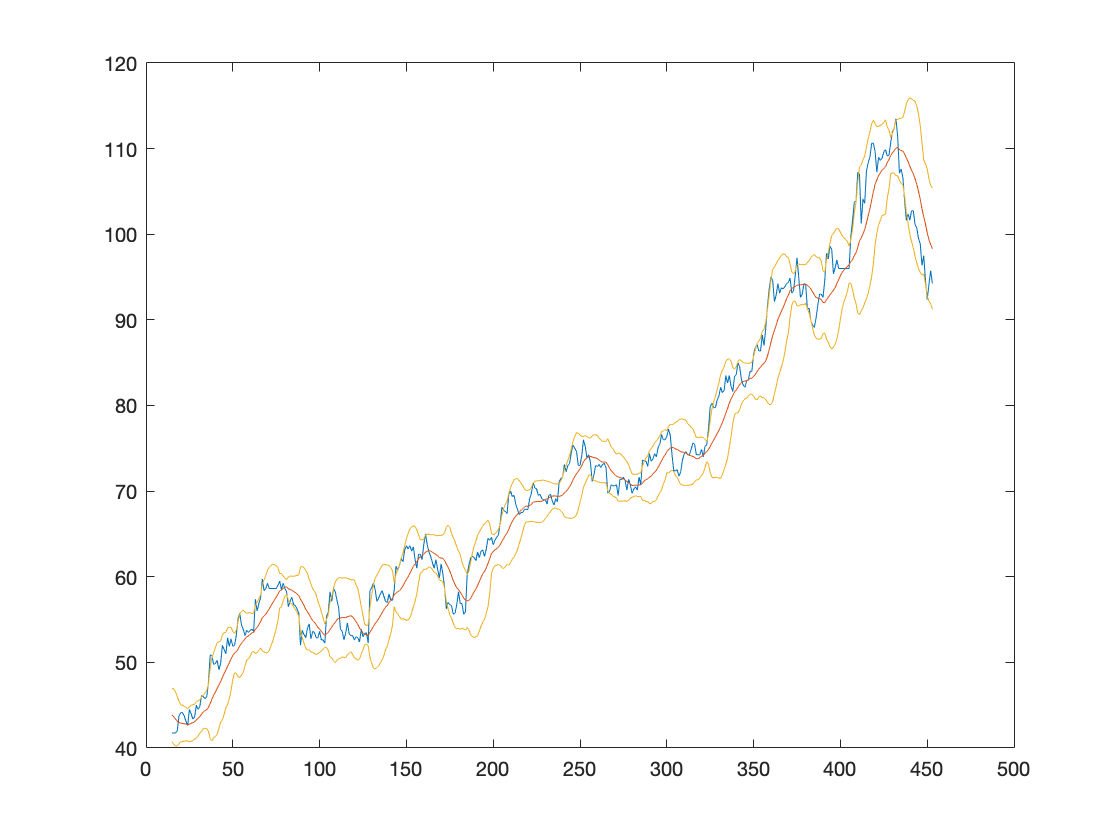

bolling(ibm(:,4),15,0)%moving average

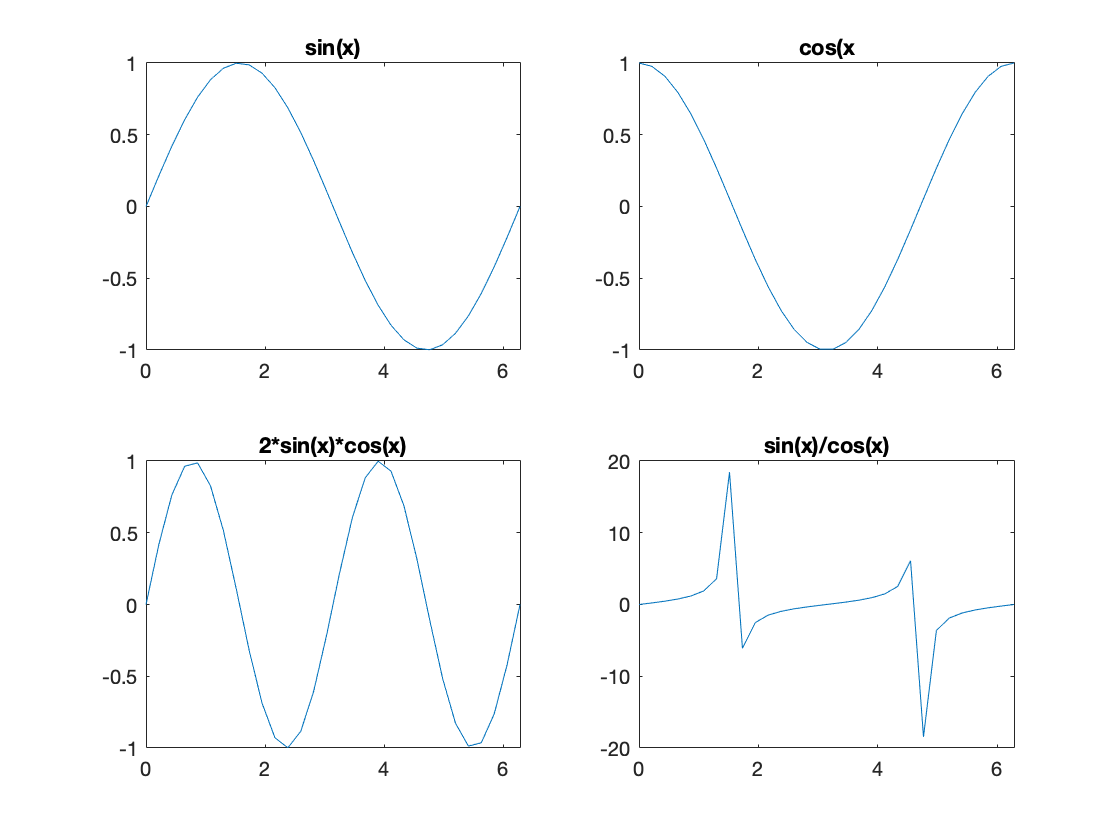

x=linspace(0,2*pi,30);
y=sin(x);
z=cos(x);
a=2.*sin(x).*cos(x);
b=sin(x)./(cos(x)+eps);
subplot(2,2,1);
plot(x,y);
title("sin(x)")
subplot(2,2,2);
plot(x,z);
title("cos(x")
subplot(2,2,3);
plot(x,a);
title("2*sin(x)*cos(x)")
subplot(2,2,4);
plot(x,b);
title("sin(x)/cos(x)")

q=randn(5000,1)%normal random distribution
